# PINNs with plane stress plate (body force x and y)

- 1 neural networks - for body force x=1 and y=1 only

- 4 inputs - x, y, B, H

- limitation due to body force

tic
clear; close all; clc;

## 1. Definition of the network

layers = [
    featureInputLayer(4,"Normalization","none") % 4 inputs [x, y, B, H]
    fullyConnectedLayer(64)
    tanhLayer
    fullyConnectedLayer(64)
    tanhLayer
    fullyConnectedLayer(64)
    tanhLayer
    fullyConnectedLayer(4) % 4 outputs [ux_fx, uy_fx for bodyforcex & ux_fy, uy_fy for bodyforcey] pointwise
    ];

dlnet = dlnetwork(layerGraph(layers));

## 2. Parameters

E = 1;
nu = 0.3;

% BODY FORCE
fx = 1;
fy = 1;

B_min = 1;  B_max = 3;
H_min = 1;  H_max = 3;

%Collocation points for random training dataset
numInterior = 1000; % 1000 points inside domain
numBoundary = 50; % 50 points on each of the 4 boundary

% Initialize datasets (row-wise storage)
XInterior = []; %interior points
XBoundary = []; %boundary points
UBoundary = []; %boundary values

Xtr_all.top   = [];
Xtr_all.right = [];
Xtr_all.left  = [];

% Grid nodes
nNodesX = 32;
nNodesY = 32;
nNodes = nNodesX * nNodesY;
ndofNode = 2;
nDOF = ndofNode * nNodes;

% % Reference unit mesh
% [xGrid, yGrid] = meshgrid(linspace(0,B,nNodesX), linspace(0,H,nNodesY));
% coords0 = [xGrid(:), yGrid(:)];

[xGrid, yGrid] = meshgrid(linspace(0,1,nNodesX), linspace(0,1,nNodesY));
coords0 = [xGrid(:), yGrid(:)];

## 3. Data generation

numGeom = 20;

for i = 1:numGeom
    %% =====================================================
    % GEOMETRY CREATION
    % ======================================================

    B = B_min + (B_max - B_min)*rand;
    H = H_min + (H_max - H_min)*rand;

    % Normalize geometry
    Bn = 2*(B - B_min)/(B_max - B_min) - 1;
    Hn = 2*(H - H_min)/(H_max - H_min) - 1;

    %% =====================================================
    % INTERIOR COLLOCATION POINTS
    % ======================================================

    xInt = rand(numInterior,1)*B;
    yInt = rand(numInterior,1)*H;

    % Normalize to [-1,1]
    xIntN = 2*(xInt/B) - 1;
    yIntN = 2*(yInt/H) - 1;

    Xi = [xIntN, yIntN, Bn*ones(numInterior,1), Hn*ones(numInterior,1)];

    XInterior = [XInterior; Xi];

    %% =====================================================
    % BOTTOM BOUNDARY (FIXED)
    % ======================================================

    xBot = rand(numBoundary,1)*B;
    yBot = zeros(numBoundary,1);

    xBotN = 2*(xBot/B) - 1;
    yBotN = 2*(yBot/H) - 1;

    Xb = [xBotN, yBotN, Bn*ones(numBoundary,1), Hn*ones(numBoundary,1)];

    XBoundary = [XBoundary; Xb];

    % u = 0 on bottom boundary
    UBoundary = [UBoundary;zeros(numBoundary,4)];

    %% =====================================================
    % TOP BOUNDARY (TRACTION FREE)
    % ======================================================

    xTop = rand(numBoundary,1)*B;
    yTop = H*ones(numBoundary,1);

    xTopN = 2*(xTop/B) - 1;
    yTopN = 2*(yTop/H) - 1;

    Xt = [xTopN, yTopN, Bn*ones(numBoundary,1), Hn*ones(numBoundary,1)];

    Xtr_all.top = [Xtr_all.top; Xt];

    %% =====================================================
    % LEFT BOUNDARY (TRACTION FREE)
    % ======================================================

    xLeft = zeros(numBoundary,1);
    yLeft = rand(numBoundary,1)*H;

    xLeftN = 2*(xLeft/B) - 1;
    yLeftN = 2*(yLeft/H) - 1;

    Xl = [xLeftN, yLeftN, Bn*ones(numBoundary,1), Hn*ones(numBoundary,1)];

    Xtr_all.left = [Xtr_all.left; Xl];

    %% =====================================================
    % RIGHT BOUNDARY (TRACTION FREE)
    % ======================================================

    xRight = B*ones(numBoundary,1);
    yRight = rand(numBoundary,1)*H;

    xRightN = 2*(xRight/B) - 1;
    yRightN = 2*(yRight/H) - 1;

    Xr = [xRightN, yRightN, Bn*ones(numBoundary,1), Hn*ones(numBoundary,1)];

    Xtr_all.right = [Xtr_all.right; Xr];

end

disp('Geometries generation completed!');

Geometries generation completed!


disp('Data generation time:');

Data generation time:


toc

Elapsed time is 5.590719 seconds.


## 4. Training Loop

tic
numEpochs = 6000;
learnRate = 1e-3;

avgGrad = [];
avgSqGrad = [];

% Convert ALL datasets to dlarray
dlXInt = dlarray(XInterior','CB');
dlXB   = dlarray(XBoundary','CB');
dlUB   = dlarray(UBoundary','CB');

dlXtr.top   = dlarray(Xtr_all.top','CB');
dlXtr.right = dlarray(Xtr_all.right','CB');
dlXtr.left  = dlarray(Xtr_all.left','CB');

for epoch = 1:numEpochs

    [loss, loss_pde_x, loss_pde_y, loss_bc, loss_tr, gradients] = dlfeval(@pinnLoss, ...
        dlnet, dlXInt, dlXB, dlUB, dlXtr, E, nu, fx, fy, B_min, B_max, H_min, H_max);
    [dlnet, avgGrad, avgSqGrad] = adamupdate(dlnet, gradients, avgGrad, avgSqGrad, epoch, learnRate);

    if mod(epoch,500)==0
        fprintf("Epoch %d | Loss %.6f | PDEx %.6f | PDEy %.6f | BC %.6f | TR %.6f\n", epoch, ...
            extractdata(loss), extractdata(loss_pde_x), extractdata(loss_pde_y), extractdata(loss_bc), extractdata(loss_tr));
    end

    if epoch > 5000
    learnRate = 1e-4;
    end
end

Epoch 500 | Loss 0.182887 | PDEx 0.079821 | PDEy 0.006421 | BC 0.020905 | TR 0.075740
Epoch 1000 | Loss 0.127153 | PDEx 0.047667 | PDEy 0.003970 | BC 0.020238 | TR 0.055277
Epoch 1500 | Loss 0.107204 | PDEx 0.036656 | PDEy 0.003481 | BC 0.018403 | TR 0.048664
Epoch 2000 | Loss 0.080916 | PDEx 0.027760 | PDEy 0.002852 | BC 0.015965 | TR 0.034340
Epoch 2500 | Loss 0.086903 | PDEx 0.031502 | PDEy 0.002924 | BC 0.013876 | TR 0.038601
Epoch 3000 | Loss 0.059595 | PDEx 0.020783 | PDEy 0.002280 | BC 0.012007 | TR 0.024524
Epoch 3500 | Loss 0.052419 | PDEx 0.018345 | PDEy 0.002031 | BC 0.010704 | TR 0.021340
Epoch 4000 | Loss 0.046767 | PDEx 0.016453 | PDEy 0.001818 | BC 0.009704 | TR 0.018792
Epoch 4500 | Loss 0.043463 | PDEx 0.015312 | PDEy 0.001645 | BC 0.008984 | TR 0.017522
Epoch 5000 | Loss 0.038907 | PDEx 0.013526 | PDEy 0.001541 | BC 0.008337 | TR 0.015503
Epoch 5500 | Loss 0.038456 | PDEx 0.013225 | PDEy 0.001534 | BC 0.008230 | TR 0.015467
Epoch 6000 | Loss 0.037992 | PDEx 0.013061 |


disp("✅ PINN training completed");

✅ PINN training completed


disp('Training time:')

Training time:


toc

Elapsed time is 14907.170540 seconds.


## 5. Inference


% Global text formatting configuration
set(groot, ...
    'DefaultAxesFontSize', 20, ...     % For ticks, x/y/z labels
    'DefaultTextFontSize', 20, ...     % For manually added text objects
    'DefaultLegendFontSize', 20);      % For graph legends
tic
% Test geometry
Btest = 1.25;
Htest = 2;

fx_test = 2;
fy_test = 3;

bodyforcetestx = [fx_test;0];
bodyforcetesty = [0;fy_test];

coords = [coords0(:,1)*Btest, coords0(:,2)*Htest];

% Normalize spatial coordinates
xtestN = 2*(coords(:,1)'./Btest) - 1;
ytestN = 2*(coords(:,2)'./Htest) - 1;

% Normalize geometry inputs
BtestN = 2*(Btest - B_min)/(B_max - B_min) - 1;
HtestN = 2*(Htest - H_min)/(H_max - H_min) - 1;

BtestN_vec = BtestN * ones(size(xtestN));
HtestN_vec = HtestN * ones(size(ytestN));

% 4-input PINN input: [xN; yN; BN; HN]
Xtest_nodes = dlarray(single([xtestN; ytestN; BtestN_vec; HtestN_vec]), "CB");

% ============================================
% PINN SOLUTION - DISPLACEMENT
% ============================================
U_pred = forward(dlnet, Xtest_nodes);

ux_fx = U_pred(1,:);
uy_fx = U_pred(2,:);

ux_fy = U_pred(3,:);
uy_fy = U_pred(4,:);

ux_total = fx_test*ux_fx + fy_test*ux_fy;
uy_total = fx_test*uy_fx + fy_test*uy_fy;

u_x_PINN = extractdata(ux_total)';
u_y_PINN = extractdata(uy_total)';

UxN = reshape(u_x_PINN, nNodesY, nNodesX);
UyN = reshape(u_y_PINN, nNodesY, nNodesX);

disp('Inference Time:')

Inference Time:


toc

Elapsed time is 4.672498 seconds.



tic
% ============================================
% FEM SOLUTION
% ============================================

[K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyforcetestx);
[K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyforcetesty);

% apply base fixed BC (y==0)
tol = 1e-6;
baseNodes = find(abs(coords(:,2)) < tol);
fixedDOFs = reshape([(baseNodes-1)'*ndofNode + 1; (baseNodes-1)'*ndofNode + 2], [], 1);
allDOFs = (1:nDOF)';
freeDOFs = setdiff(allDOFs, fixedDOFs);

u_fem1 = zeros(nDOF,1);
u_fem2 = zeros(nDOF,1);

u_fem1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);
u_fem2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);

u_FEM1 = u_fem1(:);
u_FEM2 = u_fem2(:);

% extract u_x and u_y components
u_x_FEM1 = u_FEM1(1:2:end);
u_y_FEM1 = u_FEM1(2:2:end);

u_x_FEM2 = u_FEM2(1:2:end);
u_y_FEM2 = u_FEM2(2:2:end);

% reshape on grid
Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
Ycoords = reshape(coords(:,2), nNodesY, nNodesX);

UxF1 = reshape(u_x_FEM1, nNodesY, nNodesX);
UyF1 = reshape(u_y_FEM1, nNodesY, nNodesX);

UxF2 = reshape(u_x_FEM2, nNodesY, nNodesX);
UyF2 = reshape(u_y_FEM2, nNodesY, nNodesX);

UxF = UxF1 + UxF2;
UyF = UyF1 + UyF2;

% ============================================
% COMBINED DISPLACEMENT ERROR METRICS
% ============================================

% Assemble FEM and PINN displacement vectors in DOF order: [ux1; uy1; ux2; uy2; ...]
u_FEM = zeros(nDOF,1);
u_PINN = zeros(nDOF,1);

u_FEM(1:2:end) = UxF(:);
u_FEM(2:2:end) = UyF(:);

u_PINN(1:2:end) = UxN(:);
u_PINN(2:2:end) = UyN(:);

% Error vector
err_vec = u_FEM - u_PINN;

% Error measures
RMSE = norm(err_vec) / sqrt(numel(err_vec));
relL2 = norm(err_vec, 2) / norm(u_FEM, 2);
relLinf = norm(err_vec, Inf) / norm(u_FEM, Inf);

fprintf('\nCombined displacement errors:\n');


Combined displacement errors:


fprintf('RMSE                     = %.3e\n', RMSE);

RMSE                     = 6.167e+00


fprintf('Relative L2 error        = %.3e\n', relL2);

Relative L2 error        = 3.457e-01


fprintf('Relative infinity error  = %.3e\n', relLinf);

Relative infinity error  = 3.742e-01



% RELATIVE L2 ERRORS FOR BOTH DISPLACEMENTS SEPARARELY

relErrUx = norm(UxF(:)-UxN(:)) / norm(UxF(:));
relErrUy = norm(UyF(:)-UyN(:)) / norm(UyF(:));

fprintf('\nRelative L2 Error ux = %.3e\n', relErrUx);


Relative L2 Error ux = 3.459e-01


fprintf('Relative L2 Error uy = %.3e\n', relErrUy);

Relative L2 Error uy = 3.432e-01


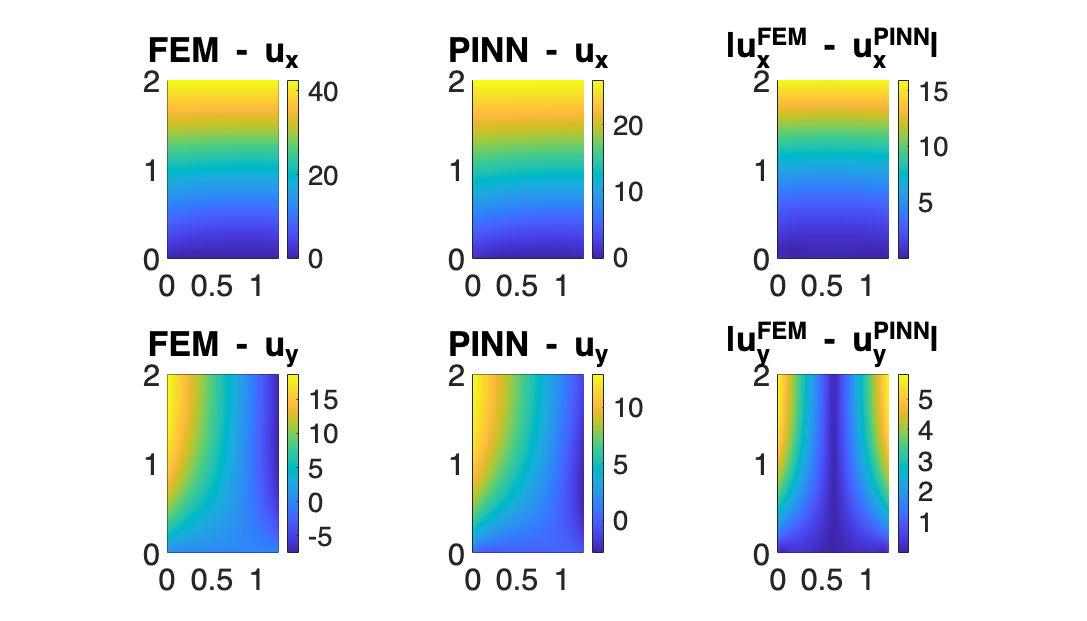


% ============================================
% ABSOLUTE ERROR
% ============================================

Err_u = abs(UxF - UxN);
Err_v = abs(UyF - UyN);

% Coordinates reshaped
Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
Ycoords = reshape(coords(:,2), nNodesY, nNodesX);

% ============================================
% PLOTS
% ============================================

figure('Position',[100 100 1400 800]);

subplot(2,3,1);
pcolor(Xcoords, Ycoords, UxF); shading interp; colorbar; axis equal tight;
title('FEM - u_x');

subplot(2,3,2);
pcolor(Xcoords, Ycoords, UxN); shading interp; colorbar; axis equal tight;
title('PINN - u_x');

subplot(2,3,3);
pcolor(Xcoords, Ycoords, Err_u); shading interp; colorbar; axis equal tight;
title('|u_x^{FEM} - u_x^{PINN}|');

subplot(2,3,4);
pcolor(Xcoords, Ycoords, UyF); shading interp; colorbar; axis equal tight;
title('FEM - u_y');

subplot(2,3,5);
pcolor(Xcoords, Ycoords, UyN); shading interp; colorbar; axis equal tight;
title('PINN - u_y');

subplot(2,3,6);
pcolor(Xcoords, Ycoords, Err_v); shading interp; colorbar; axis equal tight;
title('|u_y^{FEM} - u_y^{PINN}|');

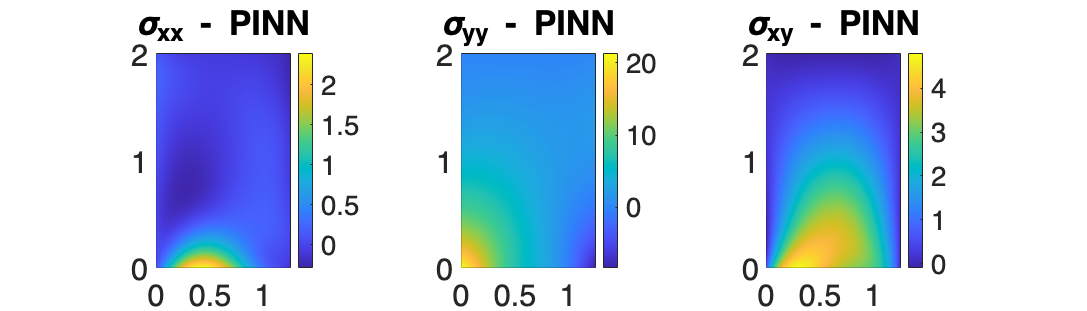



% ============================================
% PINN STRESSES
% ============================================

[sxx_fx, syy_fx, sxy_fx] = dlfeval(@computeStressCase, ...
    dlnet, Xtest_nodes, E, nu, B_min, B_max, H_min, H_max, 1);

[sxx_fy, syy_fy, sxy_fy] = dlfeval(@computeStressCase, ...
    dlnet, Xtest_nodes, E, nu, B_min, B_max, H_min, H_max, 2);

sxx_pred = fx_test*sxx_fx + fy_test*sxx_fy;
syy_pred = fx_test*syy_fx + fy_test*syy_fy;
sxy_pred = fx_test*sxy_fx + fy_test*sxy_fy;

SxxN = reshape(extractdata(sxx_pred)', nNodesY, nNodesX);
SyyN = reshape(extractdata(syy_pred)', nNodesY, nNodesX);
SxyN = reshape(extractdata(sxy_pred)', nNodesY, nNodesX);

% ============================================
% STRESS PLOTS
% ============================================

figure('Position',[100 100 1400 400]);

subplot(1,3,1);
pcolor(Xcoords, Ycoords, SxxN);
shading interp;
colorbar;
axis equal tight;
title('\sigma_{xx} - PINN');

subplot(1,3,2);
pcolor(Xcoords, Ycoords, SyyN);
shading interp;
colorbar;
axis equal tight;
title('\sigma_{yy} - PINN');

subplot(1,3,3);
pcolor(Xcoords, Ycoords, SxyN);
shading interp;
colorbar;
axis equal tight;
title('\sigma_{xy} - PINN');


disp('Plotting time:')

Plotting time:


toc

Elapsed time is 5.493026 seconds.


## Functions

function [loss, loss_pde_x, loss_pde_y, loss_bc, loss_tr, gradients] = pinnLoss( ...
    dlnet, X, Xbc, UBoundary, Xtr, E, nu, fx, fy, B_min, B_max, H_min, H_max)    
    
    Bn = X(3,:);
    Hn = X(4,:);
    
    B = (Bn + 1)/2 * (B_max - B_min) + B_min;
    H = (Hn + 1)/2 * (H_max - H_min) + H_min;

    % ============================================================
    % 1️⃣ Forward Pass
    % ============================================================
    U = forward(dlnet, X);
    % ux = U(1,:);
    % uy = U(2,:);

    ux_fx = U(1,:);   % displacement ux due to fx = 1, fy = 0
    uy_fx = U(2,:);   % displacement uy due to fx = 1, fy = 0

    ux_fy = U(3,:);   % displacement ux due to fx = 0, fy = 1
    uy_fy = U(4,:);   % displacement uy due to fx = 0, fy = 1

    % ============================================================
    % 2️⃣ Derivatives (chain rule scaling)
    % ============================================================
    gradUx_fx = dlgradient(sum(ux_fx), X,'EnableHigherDerivatives', true);
    gradUy_fx = dlgradient(sum(uy_fx), X,'EnableHigherDerivatives', true);

    gradUx_fy = dlgradient(sum(ux_fy), X,'EnableHigherDerivatives', true);
    gradUy_fy = dlgradient(sum(uy_fy), X,'EnableHigherDerivatives', true);

    dux_dx_fx = gradUx_fx(1,:) .* (2 ./ B);
    dux_dy_fx = gradUx_fx(2,:) .* (2 ./ H);
    duy_dx_fx = gradUy_fx(1,:) .* (2 ./ B);
    duy_dy_fx = gradUy_fx(2,:) .* (2 ./ H);

    dux_dx_fy = gradUx_fy(1,:) .* (2 ./ B);
    dux_dy_fy = gradUx_fy(2,:) .* (2 ./ H);
    duy_dx_fy = gradUy_fy(1,:) .* (2 ./ B);
    duy_dy_fy = gradUy_fy(2,:) .* (2 ./ H);

    % ============================================================
    % 3️⃣ Strain
    % ============================================================
    exx_fx = dux_dx_fx;
    eyy_fx = duy_dy_fx;
    % exy = 0.5*(dux_dy + duy_dx); %tensor shear strain
    gxy_fx = dux_dy_fx + duy_dx_fx; %engineering shear strain

    exx_fy = dux_dx_fy;
    eyy_fy = duy_dy_fy;
    gxy_fy = dux_dy_fy + duy_dx_fy; %engineering shear strain
    
    % ============================================================
    % 4️⃣ Stress (plane stress)
    % ============================================================
    C = E/(1 - nu^2);
    G = E/(2*(1+nu));

    sxx_fx = C*(exx_fx + nu*eyy_fx);
    syy_fx = C*(eyy_fx + nu*exx_fx);
    % sxy = C*(1 - nu)*exy;
    sxy_fx = G * gxy_fx;

    sxx_fy = C*(exx_fy + nu*eyy_fy);
    syy_fy = C*(eyy_fy + nu*exx_fy);
    sxy_fy = G * gxy_fy;
    
    % ============================================================
    % 5️⃣ PDE (equilibrium)
    % ============================================================
    gradSxx_fx = dlgradient(sum(sxx_fx), X, 'EnableHigherDerivatives', true);
    gradSxy_fx = dlgradient(sum(sxy_fx), X, 'EnableHigherDerivatives', true);
    gradSyy_fx = dlgradient(sum(syy_fx), X, 'EnableHigherDerivatives', true);

    gradSxx_fy = dlgradient(sum(sxx_fy), X, 'EnableHigherDerivatives', true);
    gradSxy_fy = dlgradient(sum(sxy_fy), X, 'EnableHigherDerivatives', true);
    gradSyy_fy = dlgradient(sum(syy_fy), X, 'EnableHigherDerivatives', true);

    dsxx_dx_fx = gradSxx_fx(1,:) .* (2 ./ B);
    dsxy_dy_fx = gradSxy_fx(2,:) .* (2 ./ H);
    dsxy_dx_fx = gradSxy_fx(1,:) .* (2 ./ B);
    dsyy_dy_fx = gradSyy_fx(2,:) .* (2 ./ H);

    dsxx_dx_fy = gradSxx_fy(1,:) .* (2 ./ B);
    dsxy_dy_fy = gradSxy_fy(2,:) .* (2 ./ H);
    dsxy_dx_fy = gradSxy_fy(1,:) .* (2 ./ B);
    dsyy_dy_fy = gradSyy_fy(2,:) .* (2 ./ H);

    res1_x = dsxx_dx_fx + dsxy_dy_fx + fx;
    res2_x = dsxy_dx_fx + dsyy_dy_fx + 0;

    res1_y = dsxx_dx_fy + dsxy_dy_fy + 0;
    res2_y = dsxy_dx_fy + dsyy_dy_fy + fy;

    loss_pde_x = mean(res1_x.^2,'all') + mean(res2_x.^2,'all');
    loss_pde_y = mean(res1_y.^2,'all') + mean(res2_y.^2,'all');
    
    % ============================================================
    % 6️⃣ BOUNDARY CONDITION (y = 0 → fixed)
    % ============================================================
    % Ubc = forward(dlnet, Xbc);
    % loss_bc = mean((Ubc - UBoundary).^2, 'all');
    Ubc = forward(dlnet, Xbc);
    loss_bc = mean(Ubc.^2, 'all');

    % ============================================================
    % 7️⃣ Traction BC
    % ============================================================
    loss_tr = 0;
    
    % if size(Xtr.top,2) > 0
    %     [~, syy, sxy] = computeStress(dlnet, Xtr.top, E, nu, B_min, B_max, H_min, H_max);
    %     loss_tr = loss_tr + mean(syy.^2,'all') + mean(sxy.^2,'all');
    % end
    % 
    % if size(Xtr.right,2) > 0
    %     [sxx, ~, sxy] = computeStress(dlnet, Xtr.right, E, nu, B_min, B_max, H_min, H_max);
    %     loss_tr = loss_tr + mean(sxx.^2,'all') + mean(sxy.^2, 'all');
    % end
    % 
    % if size(Xtr.left,2) > 0
    %     [sxx, ~, sxy] = computeStress(dlnet, Xtr.left, E, nu, B_min, B_max, H_min, H_max);
    %     loss_tr = loss_tr + mean(sxx.^2,'all') + mean(sxy.^2,'all');
    % end
    % 
    % loss_tr = 0;

    if size(Xtr.top,2) > 0
        [~, syy_x, sxy_x] = computeStressCase(dlnet, Xtr.top, E, nu, B_min, B_max, H_min, H_max, 1);
        [~, syy_y, sxy_y] = computeStressCase(dlnet, Xtr.top, E, nu, B_min, B_max, H_min, H_max, 2);

        loss_tr = loss_tr + mean(syy_x.^2,'all') + mean(sxy_x.^2,'all') ...
            + mean(syy_y.^2,'all') + mean(sxy_y.^2,'all');
    end

    if size(Xtr.right,2) > 0
        [sxx_x, ~, sxy_x] = computeStressCase(dlnet, Xtr.right, E, nu, B_min, B_max, H_min, H_max, 1);
        [sxx_y, ~, sxy_y] = computeStressCase(dlnet, Xtr.right, E, nu, B_min, B_max, H_min, H_max, 2);

        loss_tr = loss_tr + mean(sxx_x.^2,'all') + mean(sxy_x.^2,'all') ...
            + mean(sxx_y.^2,'all') + mean(sxy_y.^2,'all');
    end

    if size(Xtr.left,2) > 0
        [sxx_x, ~, sxy_x] = computeStressCase(dlnet, Xtr.left, E, nu, B_min, B_max, H_min, H_max, 1);
        [sxx_y, ~, sxy_y] = computeStressCase(dlnet, Xtr.left, E, nu, B_min, B_max, H_min, H_max, 2);

        loss_tr = loss_tr + mean(sxx_x.^2,'all') + mean(sxy_x.^2,'all') ...
            + mean(sxx_y.^2,'all') + mean(sxy_y.^2,'all');
    end

    % ============================================================
    % Final loss
    % ============================================================
    Wbc = 1;
    Wtr = 1;
    
    loss = loss_pde_x + loss_pde_y + Wbc*loss_bc + Wtr*loss_tr;
    
    gradients = dlgradient(loss, dlnet.Learnables);
end

function [sxx, syy, sxy] = computeStressCase(dlnet, X, E, nu, B_min, B_max, H_min, H_max, caseID)

    Bn = X(3,:);
    Hn = X(4,:);
    
    B = (Bn + 1)/2 * (B_max - B_min) + B_min;
    H = (Hn + 1)/2 * (H_max - H_min) + H_min;

    % ============================================================
    % 1️⃣ Forward Pass
    % ============================================================
    U = forward(dlnet, X);

    if caseID == 1
        ux = U(1,:);
        uy = U(2,:);
    elseif caseID == 2
        ux = U(3,:);
        uy = U(4,:);
    end

    % ux = U(1,:);
    % uy = U(2,:);
    
    % ============================================================
    % 2️⃣ Derivatives (chain rule scaling)
    % ============================================================
    gradUx = dlgradient(sum(ux), X,'EnableHigherDerivatives', true);
    gradUy = dlgradient(sum(uy), X,'EnableHigherDerivatives', true);

    dux_dx = gradUx(1,:) .* (2 ./ B);
    dux_dy = gradUx(2,:) .* (2 ./ H);

    duy_dx = gradUy(1,:) .* (2 ./ B);
    duy_dy = gradUy(2,:) .* (2 ./ H);
    % ============================================================
    % 3️⃣ Strain
    % ============================================================
    exx = dux_dx;
    eyy = duy_dy;
    % exy = 0.5*(dux_dy + duy_dx); %tensor shear strain
    gxy = dux_dy + duy_dx; %engineering shear strain
    
    % ============================================================
    % 4️⃣ Stress (plane stress)
    % ============================================================
    C = E/(1 - nu^2);
    sxx = C*(exx + nu*eyy);
    syy = C*(eyy + nu*exx);
    % sxy = C*(1 - nu)*exy;
    G = E/(2*(1+nu));
    sxy = G * gxy;  %tau xy

end

function [K,F] = buildPlaneStressFEM(coords,nx,ny,E,nu,bodyForce)
    % Structured mesh of 4-node bilinear quadrilateral elements
    nNodes = nx*ny;
    nElemX = nx-1; nElemY = ny-1;
    nElem = nElemX * nElemY;
    ndofNode = 2;
    nDOF = nNodes * ndofNode; %total dof of system

    % element connectivity matrix
    % (ix, iy) is one quadrilateral element
    conn = zeros(nElem,4);
    for ix = 1:nElemX
        for jy = 1:nElemY
            n1 = (ix-1)*ny + jy;
            n2 = ix*ny + jy;
            n3 = ix*ny + (jy+1);
            n4 = (ix-1)*ny + (jy+1);
            e = (ix-1)*nElemY + jy; %This converts the 2D element index (ix, jy) into a single element number
            conn(e,:) = [n1 n2 n3 n4]; %Element e connects nodes n1, n2, n3, n4
        end
    end

    K = zeros(nDOF);
    F = zeros(nDOF,1);

    % Plane stress constitutive matrix
    D = E / (1 - nu^2) * [1, nu, 0;
                          nu, 1, 0;
                          0, 0, (1-nu)/2];

    % 2x2 Gauss
    gp = [-1/sqrt(3), 1/sqrt(3)];
    wgp = [1,1];

    for e = 1:nElem
        nodes = conn(e,:);
        xe = coords(nodes,1);
        ye = coords(nodes,2);

        %element stiffness and force matrix
        Ke = zeros(8,8);
        Fe = zeros(8,1);

        % Reduced integration term B0 for shear (as in original)
        xi = 0; eta = 0;
        [N0, dNdxi0, dNdeta0] = shape4(xi,eta);
        J0 = [dNdxi0'; dNdeta0'] * [xe, ye];
        detJ0 = det(J0);
        invJ0 = inv(J0);
        dN0 = [dNdxi0, dNdeta0] * invJ0;

        B0 = zeros(3,8);
        for a = 1:4
            dNx = dN0(a,1);
            dNy = dN0(a,2);
            col = (a-1)*2;
            B0(1, col + 1) = dNx;
            B0(2, col + 2) = dNy;
            B0(3, col + 1) = dNy;
            B0(3, col + 2) = dNx;
        end

        for i = 1:2
            for j = 1:2
                xi = gp(i); eta = gp(j);
                [N, dNdxi, dNdeta] = shape4(xi,eta);
                J = [dNdxi'; dNdeta'] * [xe, ye];
                detJ = det(J);
                invJ = inv(J);
                dN = [dNdxi, dNdeta] * invJ;

                B = zeros(3,8);
                for a = 1:4
                    dNx = dN(a,1);
                    dNy = dN(a,2);
                    col = (a-1)*2;
                    B(1, col + 1) = dNx;
                    B(2, col + 2) = dNy;
                    B(3, col + 1) = dNy;
                    B(3, col + 2) = dNx;
                end

                % replace shear row with reduced B0 shear row
                B(3,:) = B0(3,:);

                Ke = Ke + (B' * D * B) * detJ * wgp(i) * wgp(j);

                Nmat = zeros(2,8);
                for a = 1:4
                    Nmat(1, (a-1)*2 + 1) = N(a);
                    Nmat(2, (a-1)*2 + 2) = N(a);
                end
                Fe = Fe + (Nmat' * bodyForce) * detJ * wgp(i) * wgp(j);
            end
        end

        % assemble
        gdofs = zeros(8,1);
        for a = 1:4
            node = nodes(a);
            gdofs((a-1)*2 + (1:2)) = (node-1)*2 + (1:2);
        end
        K(gdofs, gdofs) = K(gdofs, gdofs) + Ke;
        F(gdofs) = F(gdofs) + Fe;
    end
end

function [N, dNdxi, dNdeta] = shape4(xi,eta)
    N = 0.25*[(1-xi)*(1-eta);
              (1+xi)*(1-eta);
              (1+xi)*(1+eta);
              (1-xi)*(1+eta)];
    dNdxi  = 0.25*[-(1-eta); (1-eta); (1+eta); -(1+eta)];
    dNdeta = 0.25*[-(1-xi); -(1+xi); (1+xi);  (1-xi)];
end



